# Tiro parabólico aleatorio

Autor: Juan Parras

Asignatura: SALT

## Descripción del problema

En física de bachiller, se estudió las ecuaciones de un tiro parabólico en dos dimensiones: llamando $x$ a la dimensión horizontal, $y$ a la vertical, $\theta \;$ al ángulo de salida, $v$ a la velocidad inicial (en módulo), $\left(x_0 ,y_0 \right)$ a la posición inicial, y considerando que $g$ es la aceleración de la gravedad, tenemos:


$$\left\lbrace \begin{array}{ll}
x=x_0 +v\cdot \cos \left(\theta \right)\cdot t & \\
y=y_0 +v\cdot \sin \left(\theta \;\right)\cdot t-\frac{1}{2}\cdot g\cdot t^2  & 
\end{array}\right.$$


Por simplicidad, consideremos que la posición inicial es el origen, es decir, $\left(x_0 ,y_0 \right)=\left(0,0\right)$. En este caso, tenemos:


$$\left\lbrace \begin{array}{ll}
x=v\cdot \cos \left(\theta \right)\cdot t & \\
y=v\cdot \sin \left(\theta \;\right)\cdot t-\frac{1}{2}\cdot g\cdot t^2  & 
\end{array}\right.$$


Es inmediato calcular el tiempo de vuelo y el alcance:

- Tiempo de vuelo ($\left.t_v \right)$: es el tiempo hasta que el móvil cae al suelo, es decir, $y=0$. Sustituyendo esta condición en la segunda ecuación, obtenemos $t_v =2\cdot v\cdot \frac{\sin \left(\theta \;\right)}{g}$

- Alcance ($\left.x_m \right)$: es la distancia a la que cae móvil. Se obtiene sustituyendo el tiempo de vuelo en la primera ecuación, obteniendo $x_m =$$v\cdot \cos \left(\theta \right)\cdot t_v =v\cdot \cos \left(\theta \right)\cdot 2\cdot v\cdot \frac{\sin \left(\theta \;\right)}{g}=\frac{v^2 }{g}\sin \left(2\theta \;\right)$, ya que $2\cdot \cos \left(\theta \;\right)\cdot \sin \left(\theta \;\right)=\sin \left(2\theta \;\right)$

Este es un experimento determinista: si conocemos todas las condiciones iniciales (velocidad inicial, ángulo de salida, gravedad), podemos calcular la distancia a la que va a caer el móvil. Puedes ver esta simulación en la siguiente figura, y ver cómo las condiciones iniciales afectan al móvil:

g = 9.8; 
v =1.8 % Velocidad inicial

v = 1.8000

theta_deg = 50% Ángulo en grados

theta_deg = 50

theta = theta_deg * pi / 180;
t_v = 2 * v * sin(theta)/g

t_v = 0.2814

x_m = v^2 * sin(2*theta) / g

x_m = 0.3256

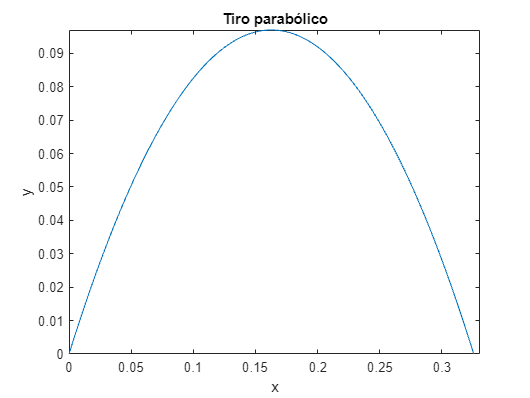


% Variables para la representación
n = 100;  % Número de puntos
t = linspace(0, t_v, n);
x = v * cos(theta) .* t;
y = v * sin(theta) .* t - 0.5 * g * t.^2;
plot(x, y)
title('Tiro parabólico')
xlabel('x')
ylabel('y')
axis([0, v^2/g, 0, max(y)])

Sin embargo, estamos asumiendo que conocemos las condiciones iniciales perfectamente. ¿Qué ocurre si tenemos incertidumbre? ¿Qué ocurre si la velocidad inicial o el ángulo son variables aleatorias?

## Ángulo como variable aleatoria

Imaginemos que el ángulo es desconocido, y por simplicidad, asumamos que $\theta \;$es una variable aleatoria uniforme, con rango $\theta \in \left\lbrack 0,\frac{\pi }{4}\right\rbrack$. Ahora, tanto el tiempo de vuelo como el alcance son también variables aleatorias, ya que ambas son transformaciones del ángulo. En otras palabras:


$$\begin{array}{l}
T_v =h\left(\theta \;\right)=2\cdot v\cdot \frac{\sin \left(\theta \;\right)}{g}\\
X_m =g\left(\theta \;\right)=\frac{v^2 }{g}\sin \left(2\theta \;\right)
\end{array}$$


En ambos casos, se trata de dos transformaciones de variable continua a continua, con lo que podemos usar el Teorema Fundamental para calcular las transformaciones. 

Por simplicidad, calcularemos sólo la segunda. Como siempre, necesitamos tres elementos:

- La fdp de la v.a. original: $f_{\theta \;} =\frac{4}{\pi \;}$ por definición, ya que $\theta \in \left\lbrack 0,\frac{\pi }{4}\right\rbrack$

- El módulo de la derivada de la transformación. Comencemos calculando la derivada: $g^{\prime } \left(\theta \right)=\frac{v^2 }{g}\cdot 2\cdot \cos \left(2\theta \;\right)$, que, como vemos en la siguiente gráfica, es positiva para todo el intervalo de interés. Por tanto, tenemos que la transformación es monónota, y además, $|g^{\prime } \left(\theta \right)|=\frac{v^2 }{g}\cdot 2\cdot \cos \left(2\theta \;\right)$ 

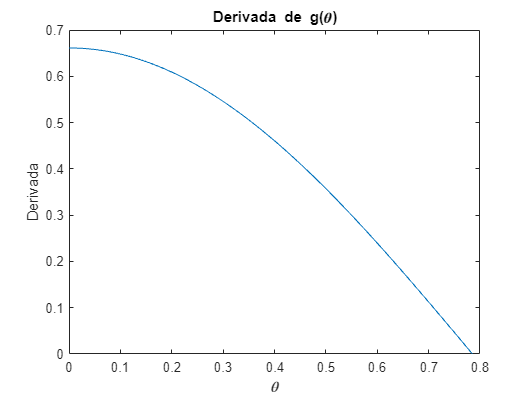

theta = linspace(0, pi/4, n);
plot(theta, v^2 / g * 2 * cos(2 * theta))
title('Derivada de g(\theta)')
xlabel('\theta')
ylabel('Derivada')

- Finalmente, necesitamos la transformada inversa. En la derivada nos aparece el $\cos \left(2\theta \;\right)$ que podemos obtener de la transformación $g\left(\theta \right)$ como sigue: $\cos \left(2\theta \right)=\sqrt{\;1-\sin^2 \left(2\theta \;\right)}=\sqrt{\;1-\frac{{\left(x_m \cdot g\right)}^2 }{v^4 }}=\frac{1}{v^2 }\sqrt{\;v^4 -{\left(x_m \cdot g\right)}^2 }$

Con lo cual, podemos obtener la fdp de $X_m$ como sigue:


$$f_{x_m } \left(x_m \right)=\frac{4\cdot g}{\pi \cdot 2\cdot \sqrt{\;v^4 -{\left(x_m \cdot g\right)}^2 }\;}$$


Y el rango de $X_m$ se obtiene de la transformación como sigue:


$$\begin{array}{l}
\theta =0\to X_m =0\\
\theta =\frac{\pi }{4}\to X_m =\frac{v^2 }{g}
\end{array}$$


Por tanto, $X_m \in \left\lbrack 0,\frac{v^2 }{g}\right\rbrack$

Representemos la fdp, que tiene una asíntota vertical:

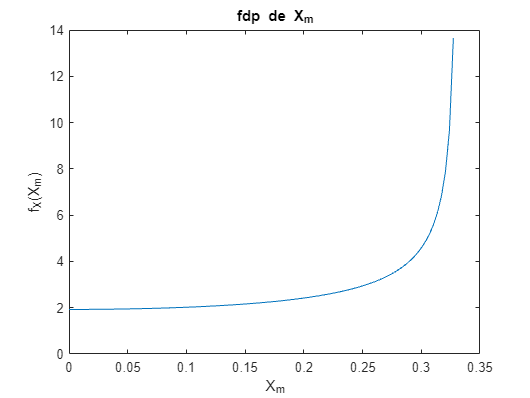

x = linspace(0, v^2/g * 0.99, n); % Definimos el rango limitados por la asíntota vertical
pdf_x = @(x) 4*g./(2*pi*sqrt(v^4 - x.^2*g^2)); % Función para calcular la pdf
plot(x, pdf_x(x))
title('fdp de X_m')
xlabel('X_m')
ylabel('f_X(X_m)')

Podemos comprobar que se trata de una fdp: es positiva en todo su dominio, y además, podemos comprobar que la integral en el rango de $X_m$ vale 1:

integral(pdf_x, 0, v^2/g)

ans = 1.0000

Finalmente, podemos realizar una simulación para comprobar que los resultados que hemos obtenido tienen sentido: para ello, seleccionamos ángulos de forma aleatoria, y calculamos el tiro parabólico para obtener valores de $X_m$:

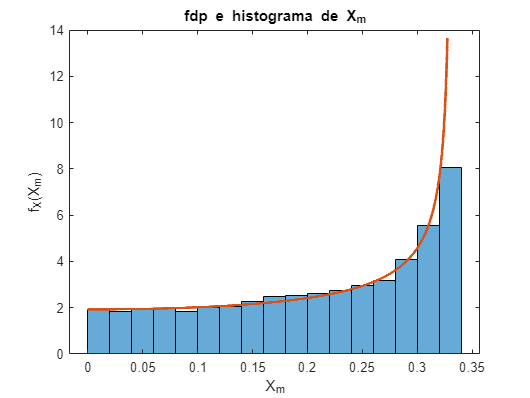

n = 10000;  % Número de simulaciones
x_m = zeros(n, 1);  % Para almacenar los valores de X_m
for i=1:n
    theta = rand(1) * pi / 4;  % Generamos theta de forma aleatoria
    x_m(i) = v^2 * sin(2*theta) / g;  % Calculamos X_m
end
% Representamos ahora el histograma y la fdp que hemos obtenido antes
histogram(x_m, 'Normalization', 'pdf');
hold on;
ax = gca;
x = linspace(0, v^2/g * 0.99, n); % Definimos el rango limitados por la asíntota vertical
plot(x, pdf_x(x), 'LineWidth', 2)
hold off
title('fdp e histograma de X_m')
xlabel('X_m')
ylabel('f_X(X_m)')

¿Qué sentido tiene esta pdf? Simplemente, nos dice que es mucho más probable que obtengamos valores de alcance cercanos al máximo, debido a la transformación no lineal que estamos realizando. Podemos ver gráficamente esto en la siguiente representación, que simula el tiro parabólico para varios ángulos $\theta \;$: es más probable que el alcance esté cerca del máximo, que en el resto de puntos del rango.

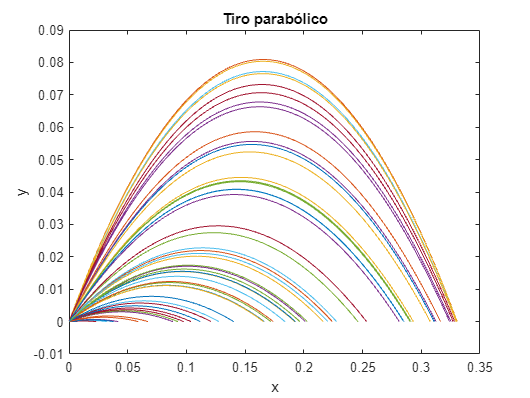

n = 100;  % Número de puntos
n_sim = 50;  % Número de trayectorias
x = zeros(n_sim, n);
y = zeros(n_sim, n);
for i=1:n_sim
    theta = rand(1) * pi / 4;  % Generamos theta de forma aleatoria
    t_v = 2 * v * sin(theta)/g;
    t = linspace(0, t_v, n);
    x(i,:) = v * cos(theta) .* t;
    y(i,:) = v * sin(theta) .* t - 0.5 * g * t.^2;
end
plot(x', y')
title('Tiro parabólico')
xlabel('x')
ylabel('y')

También es posible calcular la media y la desviación típica de $X_m$

integrando_media = @(x) x.*4*g./(2*pi*sqrt(v^4 - x.^2*g^2)); % x * f(x), el integrando de la media
integrando_vcm = @(x) x.^2.*4*g./(2*pi*sqrt(v^4 - x.^2*g^2)); % x^2 * f(x), el integrando del valor cuadrático medio

media = integral(integrando_media, 0, v^2 / g)

media = 0.2105

vcm = integral(integrando_vcm, 0, v^2 / g)

vcm = 0.0547

varianza = vcm - media ^2

varianza = 0.0104

desviacion_tipica = sqrt(varianza)

desviacion_tipica = 0.1017

Una última cuestión tiene que ver con la transformación de la media: recordemos que no es igual la media que acabamos de obtener, que es $\mathbb{E}\left\lbrack X_m \right\rbrack$, con la transformación de la media de la variable original, $g\left(\mathbb{E}\left\lbrack \theta \;\;\right\rbrack \right)$. Pero sí que se cumple que $\mathbb{E}\left\lbrack X_m \right\rbrack =\int \;x_{m\;} f_x \left(x_m \right){\mathrm{dx}}_m =\int \;g\left(\theta \;\right)\;f_{\theta \;} \left(\theta \;\right)\;d\theta \;$:

E_x = media

E_x = 0.2105

E_theta = pi / 8;  % Media de theta
g_E_theta = v^2 * sin(2*E_theta) / g

g_E_theta = 0.2338

integrando_g = @(theta) v^2 / g .* sin(2 * theta) * 4 / pi; % g(theta) * f(theta), el integrando de la transformación de la media
media_g = integral(integrando_g, 0, pi/4) % La integral es en los límites de theta

media_g = 0.2105

## Velocidad como variable aleatoria

Imaginemos ahora que el ángulo es conocido, pero la velocidad es desconocida, y por simplicidad, asumamos que $v\;$es una variable aleatoria uniforme, con rango $v\in \left\lbrack 0,1\right\rbrack$. De nuevo, tanto el tiempo de vuelo como el alcance son variables aleatorias, ya que ambas son transformaciones de la velocidad. Por facilitar los cálculos, asumiremos que $\theta =\frac{\pi }{4}$ a partir de ahora. En otras palabras:


$$\begin{array}{l}
T_v =h\left(v\;\right)=2\cdot v\cdot \frac{\sin \left(\theta \;\right)}{g}=2\cdot \frac{v}{g}\\
X_m =g\left(v\;\right)=\frac{v^2 }{g}\sin \left(2\theta \;\right)=\frac{v^2 }{g}
\end{array}$$


En ambos casos, se trata de dos transformaciones de variable continua a continua, con lo que podemos usar el Teorema Fundamental para calcular las transformaciones. 

Por simplicidad, calcularemos sólo la segunda. Como siempre, necesitamos tres elementos:

- La fdp de la v.a. original: $f_{\theta \;} =1$ por definición, ya que $v\in \left\lbrack 0,1\right\rbrack$

- El módulo de la derivada de la transformación. Comencemos calculando la derivada: $g^{\prime } \left(\theta \right)=\frac{2\cdot v}{g}$, que, como vemos en la siguiente gráfica, es positiva para todo el intervalo de interés. Por tanto, tenemos que la transformación es monónota, y además, $|g^{\prime } \left(\theta \right)|=\frac{2\cdot v}{g}$ 

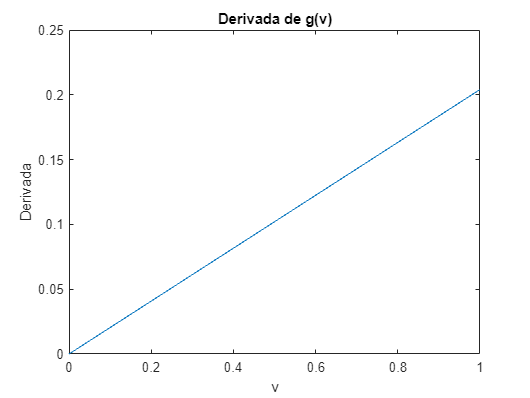

n = 100;
v = linspace(0, 1, n);
plot(v, 2 * v / g)
title('Derivada de g(v)')
xlabel('v')
ylabel('Derivada')

- Finalmente, necesitamos la transformada inversa, que en este caso es $v=\pm \sqrt{\;X_m \cdot g}$. En este caso, sólo nos afecta la raíz positiva, que es la que mantenemos. 

Con lo cual, podemos obtener la fdp de $X_m$ como sigue:


$$f_{x_m } \left(x_m \right)=\frac{g}{2\cdot \sqrt{\;x_m \cdot \;\;g}\;}$$


Y el rango de $X_m$ se obtiene de la transformación como sigue:


$$\begin{array}{l}
v=0\to X_m =0\\
v=1\to X_m =\frac{1}{g}
\end{array}$$


Por tanto, $X_m \in \left\lbrack 0,\frac{1}{g}\right\rbrack$

Representemos la fdp:

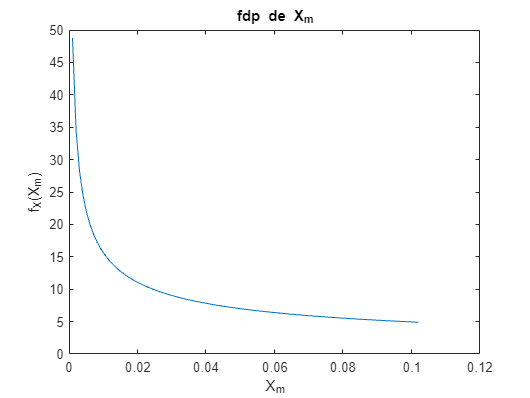

x = linspace(0, 1/g, n); % Definimos el rango
pdf_x = @(x) g./(2 * sqrt(x * g)); % Función para calcular la pdf
plot(x, pdf_x(x))
title('fdp de X_m')
xlabel('X_m')
ylabel('f_X(X_m)')

Podemos comprobar que se trata de una fdp: es positiva en todo su dominio, y además, podemos comprobar que la integral en el rango de $X_m$ vale 1:

integral(pdf_x, 0, 1/g)

ans = 1.0000

Finalmente, podemos realizar una simulación para comprobar que los resultados que hemos obtenido tienen sentido: para ello, seleccionamos velocidades de forma aleatoria, y calculamos el tiro parabólico para obtener valores de $X_m$:

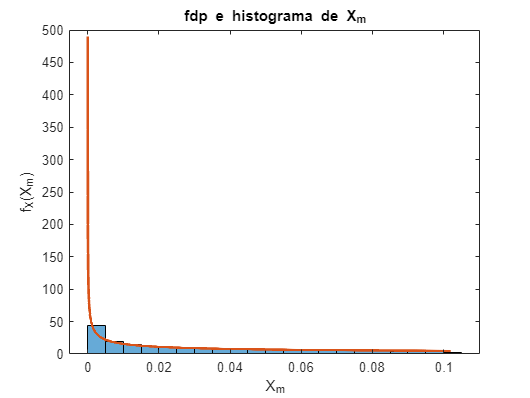

n = 10000;  % Número de simulaciones
x_m = zeros(n, 1);  % Para almacenar los valores de X_m
for i=1:n
    v = rand(1);  % Generamos v de forma aleatoria
    x_m(i) = v^2 / g;  % Calculamos X_m
end
% Representamos ahora el histograma y la fdp que hemos obtenido antes
histogram(x_m, 'Normalization', 'pdf');
hold on;
ax = gca;
x = linspace(0, 1/g, n); % Definimos el rango
plot(x, pdf_x(x), 'LineWidth', 2)
hold off
title('fdp e histograma de X_m')
xlabel('X_m')
ylabel('f_X(X_m)')

¿Qué sentido tiene esta pdf? Simplemente, nos dice que es mucho más probable que obtengamos valores de alcance pequeños, debido a la transformación que estamos realizando. Podemos ver gráficamente esto en la siguiente representación, que simula el tiro parabólico para varias velocidades: es más probable que el alcance esté cerca del origen, que en el resto de puntos del rango, ya que la distancia depende del cuadrado de la velocidad inicial.

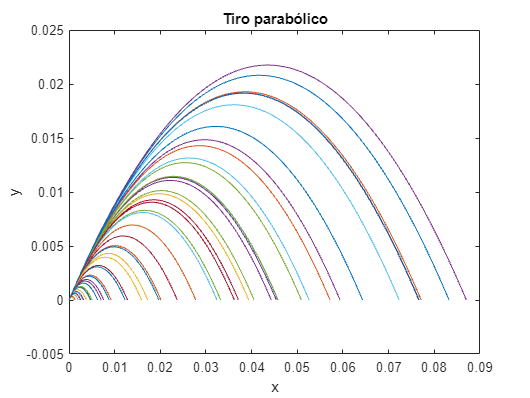

n = 100;  % Número de puntos
n_sim = 50;  % Número de trayectorias
x = zeros(n_sim, n);
y = zeros(n_sim, n);
theta = pi / 4;
for i=1:n_sim
    v = rand(1);  % Generamos v de forma aleatoria
    t_v = 2 * v * sin(theta)/g;
    t = linspace(0, t_v, n);
    x(i,:) = v * cos(theta) .* t;
    y(i,:) = v * sin(theta) .* t - 0.5 * g * t.^2;
end
plot(x', y')
title('Tiro parabólico')
xlabel('x')
ylabel('y')

También es posible calcular la media y la desviación típica de $X_m$

integrando_media = @(x) x.*g./(2 * sqrt(x * g)); % x * f(x), el integrando de la media
integrando_vcm = @(x) x.^2.*g./(2 * sqrt(x * g)); % x^2 * f(x), el integrando del valor cuadrático medio

media = integral(integrando_media, 0, 1 / g)

media = 0.0340

vcm = integral(integrando_vcm, 0, 1 / g)

vcm = 0.0021

varianza = vcm - media ^2

varianza = 9.2554e-04

desviacion_tipica = sqrt(varianza)

desviacion_tipica = 0.0304

Una última cuestión tiene que ver con la transformación de la media: recordemos que no es igual la media que acabamos de obtener, que es $\mathbb{E}\left\lbrack X_m \right\rbrack$, con la transformación de la media de la variable original, $g\left(\mathbb{E}\left\lbrack v\;\right\rbrack \right)$. Pero sí que se cumple que $\mathbb{E}\left\lbrack X_m \right\rbrack =\int \;x_{m\;} f_x \left(x_m \right){\mathrm{dx}}_m =\int \;g\left(v\right)\;f_v \left(v\right)\;\mathrm{dv}$:

E_x = media

E_x = 0.0340

E_v = 1 / 2;  % Media de v
g_E_theta = E_v^2 / g

g_E_theta = 0.0255

integrando_g = @(v) v.^2 / g * 1; % g(v) * f(v), el integrando de la transformación de la media
media_g = integral(integrando_g, 0, 1) % La integral es en los límites de v

media_g = 0.0340